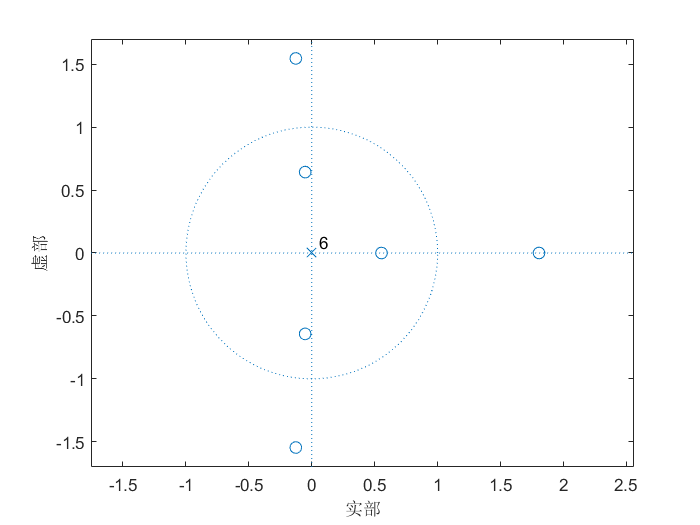

%6.2.2

%(a)
zero=[-1 2 -3 6 -3 2 -1];
zeross=roots(zero);
pole=[1 0 0 0 0 0 0 ];
poles=roots(pole);
zplane(zero,pole);

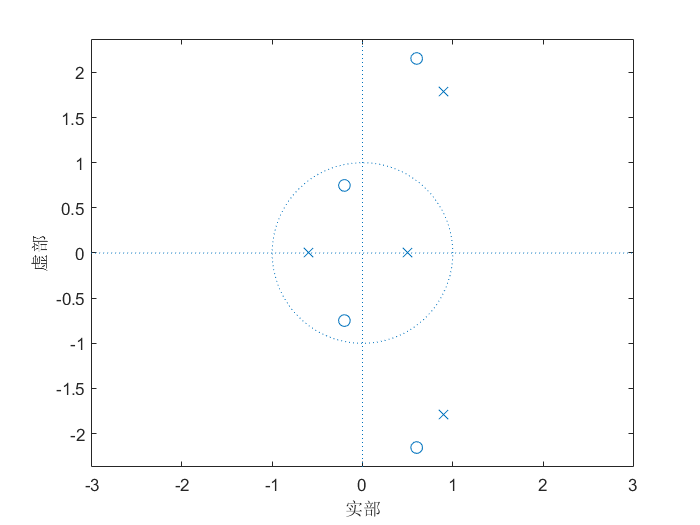


%(b)
zero1=[3 -2.4 15.36 3.84 9];
zeros1=roots(zero1);
pole1=[5 -8.5 17.6 4.7 -6];
poles1=roots(pole1);
zplane(zero1,pole1);

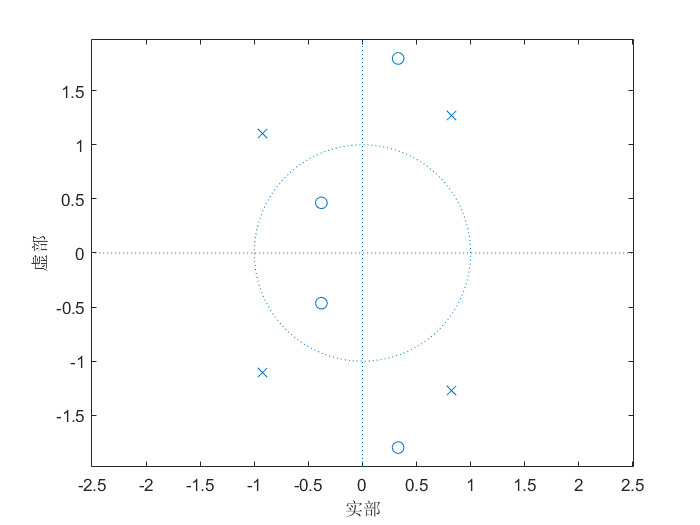


%(c)
zero2=[2 0.2 6.4 4.6 2.4];
zeros2=roots(zero2);
pole2=[5 1 6.6 4.2 24];
poles2=roots(pole2);
zplane(zero2,pole2);

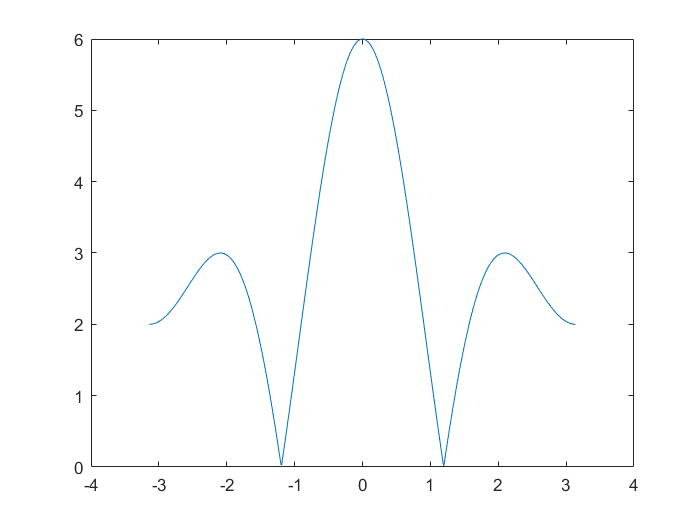


%6.2.3
%(a)
num1=[1 2 0 2 1];
den1=[1 0 0 0 0];
[mag1,phase1]=FreRes(num1,den1);
figure;
plot(-pi:0.01:pi,mag1);

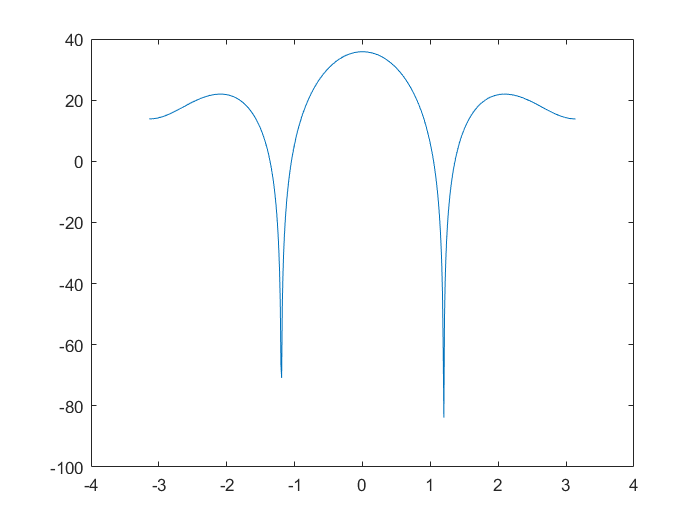

plot(-pi:0.01:pi,20*log(mag1));

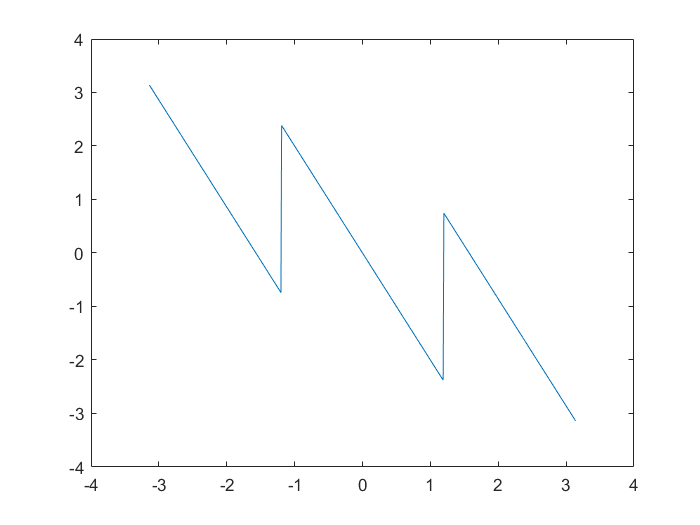

plot(-pi:0.01:pi,phase1);

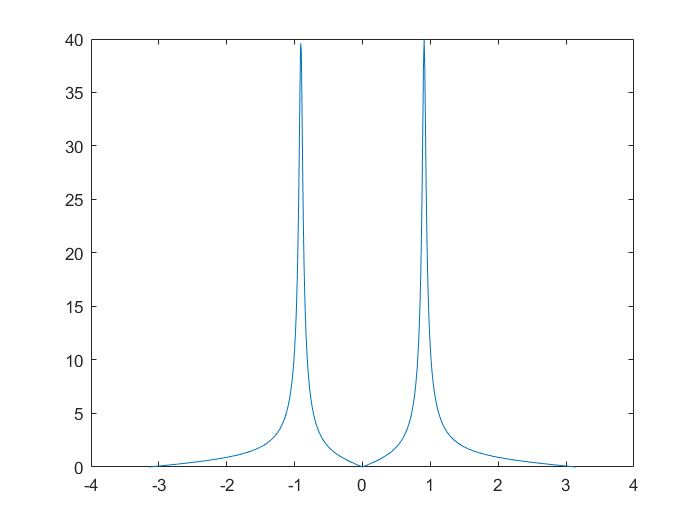


%(b)
num2=[1 0 -1];
den2=[1 -1.2 0.95];
[mag2,phase2]=FreRes(num2,den2);
figure;
plot(-pi:0.01:pi,mag2);

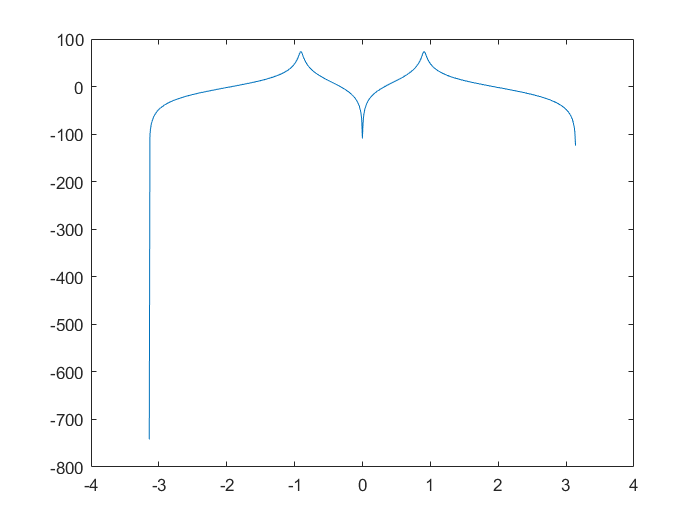

plot(-pi:0.01:pi,20*log(mag2));

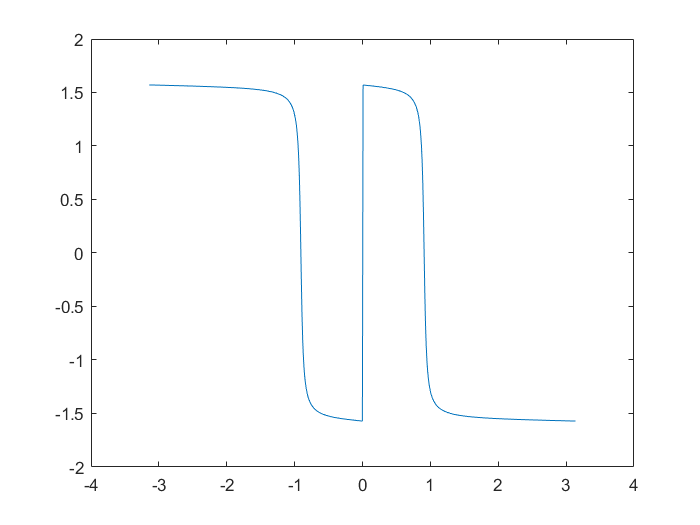

plot(-pi:0.01:pi,phase2);


%6.2.4
%(a)
b1=[3 -7.8];
a1=[1 0.9 -1.12];
[r1,p1]=partialexpansion(b1,a1)

r1 =     5.4783
   -2.4783


p1 =    -1.6000
    0.7000



%(b)
b2=[3 1.8 1.28];
a2=[1 -0.1 -0.2];
[r2,p2]=partialexpansion(b2,a2)

r2 =     3.2556
   -1.1556


p2 =     0.5000
   -0.4000


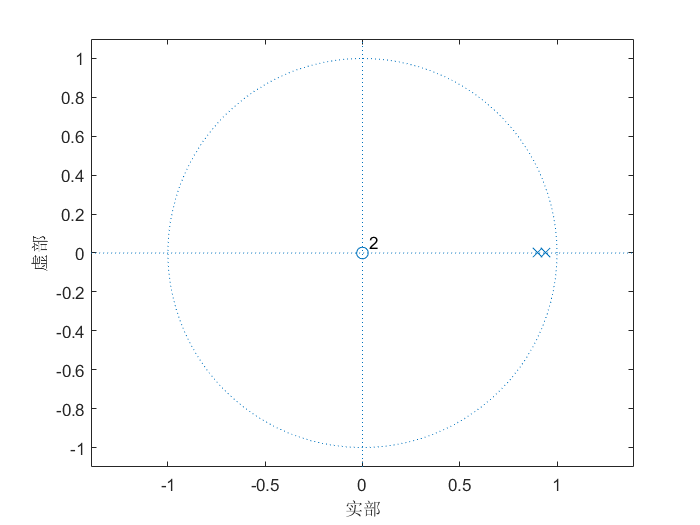


%6.2.5
c1=[1 0 0];
d1=[1 -1.845 0.850586];
c11=roots(c1);
d11=roots(d1);
zplane(c1,d1);

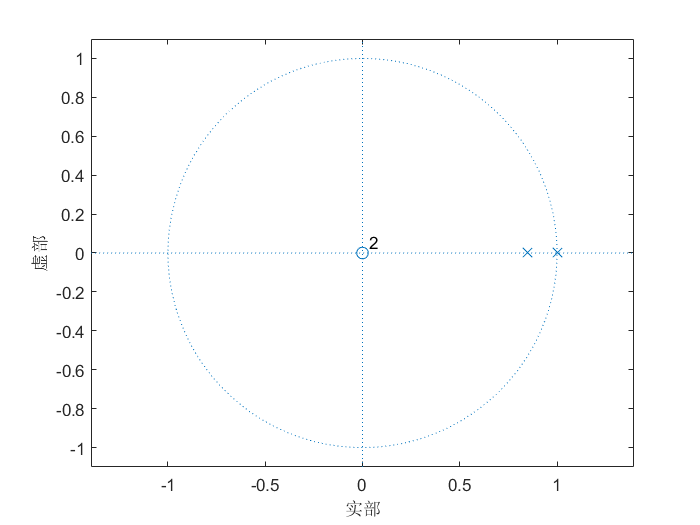


c2=[1 0 0];
d2=[1 -1.85 0.85];
c22=roots(c2);
d22=roots(d2);
zplane(c2,d2);

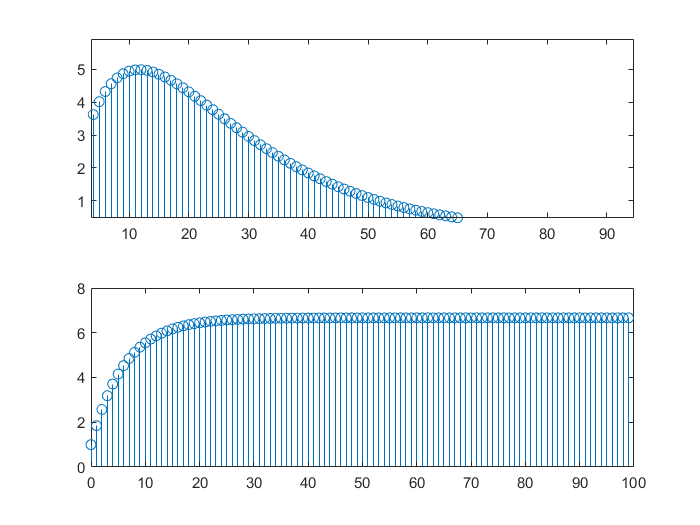


[h1,t1] =impz(c1,d1,100);
[h2,t2] =impz(c2,d2,100);
subplot(2,1,1)
stem(t1,h1);
subplot(2,1,2)
stem(t2,h2);

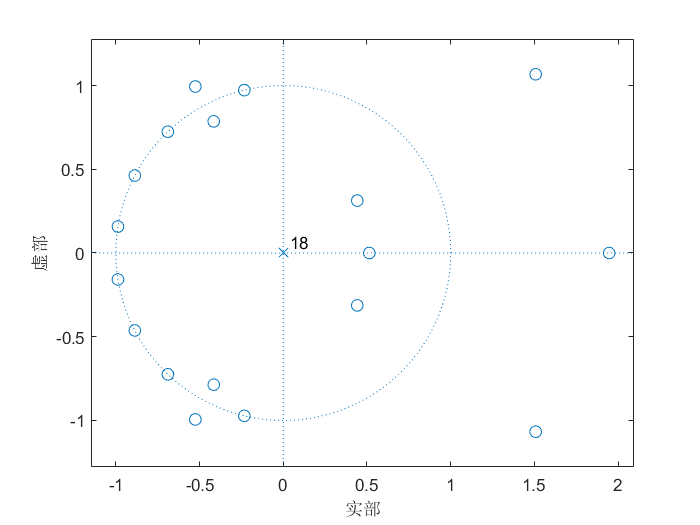


%6.3.1
hz31 = [-0.0035 -0.0039 0.0072 0.0201 -0.0000 -0.0517 -0.0506 0.0855 0.2965 0.4008 0.2965 0.0855 -0.0506 -0.0517 -0.0000 0.0201 0.0072 -0.0039 -0.0035];
hp31 = [1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0];
c31= roots(hz31);
d31=roots(hp31);
figure
zplane(c31,d31);

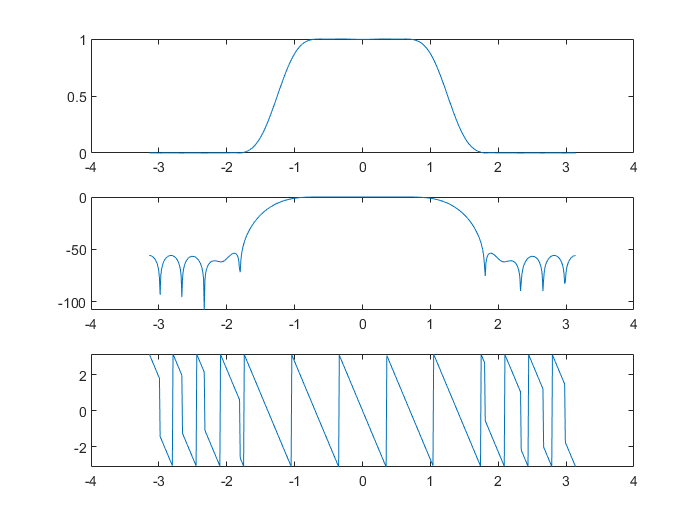


[mag31,phase31] = FreRes(hz31,hp31);
figure;
subplot(3,1,1);
plot(-pi:0.01:pi,abs(mag31));
subplot(3,1,2);
plot(-pi:0.01:pi,20*log10(mag31));
subplot(3,1,3);
plot(-pi:0.01:pi,phase31);

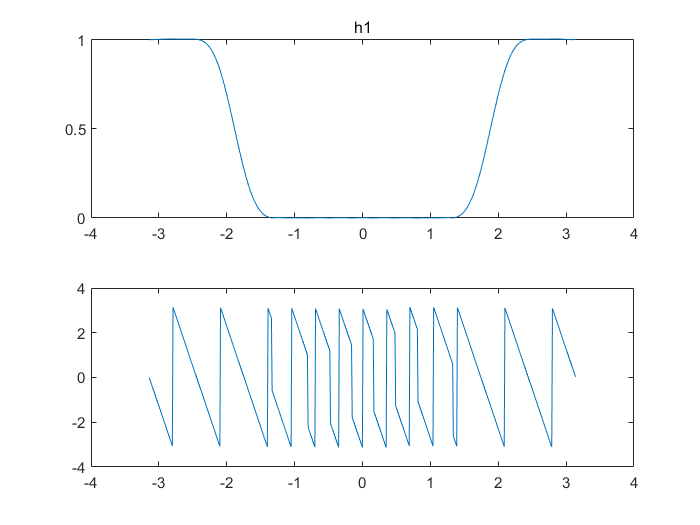


n31=0:1:18;
hz131=(-1).^n31.*(hz31);
[mag131,phase131] = FreRes(hz131,hp31);
figure;
subplot(2,1,1);
plot(-pi:0.01:pi,mag131);
title('h1')
subplot(2,1,2);
plot(-pi:0.01:pi,phase131);

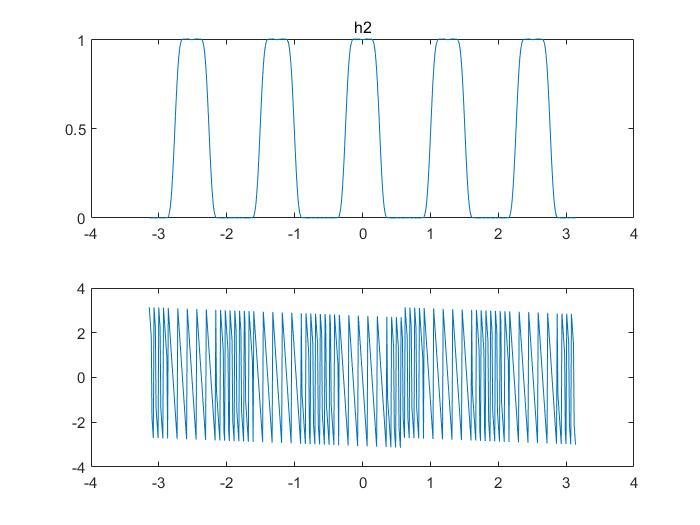


hp231 = [1 zeros(1,94)];
hz231 = [];
for i = 1:length(hz31)
    hz231= [hz231,hz31(i),0,0,0,0];
end
[mag231,phase231] = FreRes(hz231,hp231);
figure;
subplot(2,1,1);
plot(-pi:0.01:pi,mag231);
title('h2');
subplot(2,1,2);
plot(-pi:0.01:pi,phase231);

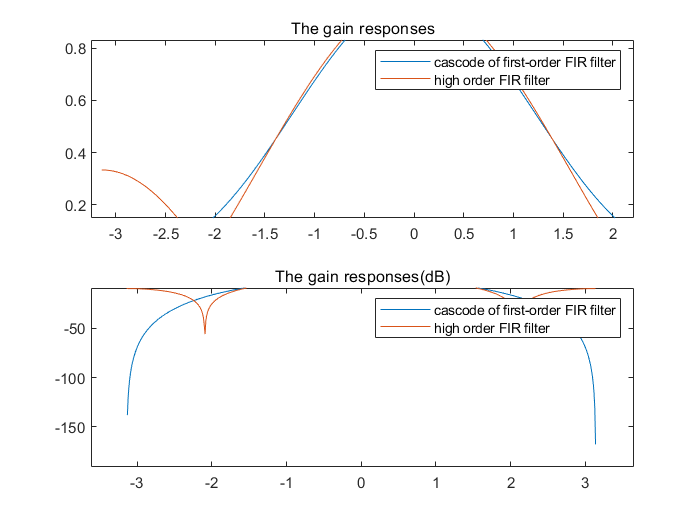


%6.3.2
b32 = [1 3 3 1];
a32 = 8;
[mag32,phase32] =FreRes(b32,a32);
figure;
subplot(2,1,1);
plot(-pi:0.01:pi,mag32);
hold on
subplot(2,1,2);
plot(-pi:0.01:pi,20*log10(abs(mag32)));

b232 = [1 1 1];
a232 = 3;
[mag232,phase232] =FreRes(b232,a232);
hold on
subplot(2,1,1);
plot(-pi:0.01:pi,mag232);
legend('cascode of first-order FIR filter','high order FIR filter');
title('The gain responses');
hold on
subplot(2,1,2);
plot(-pi:0.01:pi,20*log10(abs(mag232)));
title('The gain responses(dB)');

legend('cascode of first-order FIR filter','high order FIR filter');

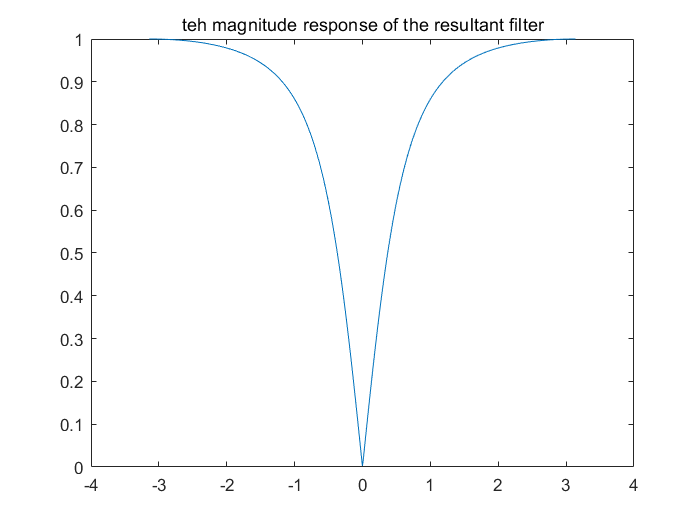


%6.4
b4 = 1.5095/2.*[1 -1];
a4 = [1 -0.5095];
figure;
[mag4,phase4]=FreRes(b4,a4);
plot(-pi:0.01:pi,mag4);
title('teh magnitude response of the resultant filter');